%***************************************************************************************
% double_pendulum.mlx
%
% Created by: Ryan S.
% Created on: 11/24/2020
%
% Comments:
%           This script was made in reference to the Animation and Solution of
%           Double Pendulum Motion from MATLAB's tutorials (link below).
%           The tutorial linked below follows a derivation of the equations
%           of motion using Newton's laws. This script differs from the
%           MATLAB tutorial by instead deriving the equations of motion
%           using the Euler-Lagrange equation for the system. This problem 
%           was taken from pg. 272 of Classical Mechanics by David Morin.
%
%           Tutorial Link:
%           https://www.mathworks.com/help/symbolic/animation-and-solution-of-double-pendulum.html
%
%***************************************************************************************

**Summary of the Lagrange Method and the Euler-Lagrange equation**

The Lagrangian of a system is defined as:


$$L\equiv T-V$$


Where *T* and *V* are the kinetic and potential energy of the system respectively.

The Euler-Lagrange equation is defined as:


$$\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial \dot{x} }\right)=\;\frac{\partial L}{\partial x}$$


Where *x* is a variable that determines the kinetic or potential energy of the system. For a Lagrangian consisting of *N* variables that define the kinetic or potential energy of a system, there will be *N* Euler-Lagrange equations (one for each variable). 

%Define variables
syms theta_1(t) theta_2(t) L_1 L_2 m_1 m_2 g

dtheta_1 = diff(theta_1);
dtheta_2 = diff(theta_2);

ddtheta_1 = diff(dtheta_1);
ddtheta_2 = diff(dtheta_2);

%Equation 1
eqn_1 = (m_1 + m_2)*L_1^2*ddtheta_1 + m_2*L_1*L_2*ddtheta_2*cos(theta_1 - theta_2) +...
    m_2*L_1*L_2*dtheta_1^2*sin(theta_1 - theta_2) + (m_1 + m_2)*g*L_1*sin(theta_1) == 0

$$eqn\_1(t) = \left(m_{1}+m_{2}\right)\,{L_{1}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+L_{2}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,L_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+L_{2}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,L_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+g\,\sin\left(\theta_{1}\left(t\right)\right)\,\left(m_{1}+m_{2}\right)\,L_{1}=0$$

%Equation 2
eqn_2 = m_2*L_2^2*ddtheta_2 + m_2*L_1*L_2*ddtheta_1*cos(theta_1 - theta_2) + ...
    -m_2*L_1*L_2*dtheta_1^2*sin(theta_1 - theta_2) + m_2*g*L_2*sin(theta_2) == 0

$$eqn\_2(t) = m_{2}\,{L_{2}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+L_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,L_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)-L_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,L_{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+g\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,L_{2}=0$$

%Initialize values
L_1 = 1;
L_2 = 1;
m_1 = 1;
m_2 = 1;
g = 9.81;

eqn_1 = subs(eqn_1);
eqn_2 = subs(eqn_2);

%Solve the nonlinear second-order differential equation

[V,S] =odeToVectorField(eqn_1,eqn_2);

%Display S
%

%Convert the first-order differential equation to a matlab func
M = matlabFunction(V,'vars',{'t','Y'});

%Solve using ode45
initCond = [pi/4 0 5*pi/6 0];
sols = ode45(M,[0,10],initCond);

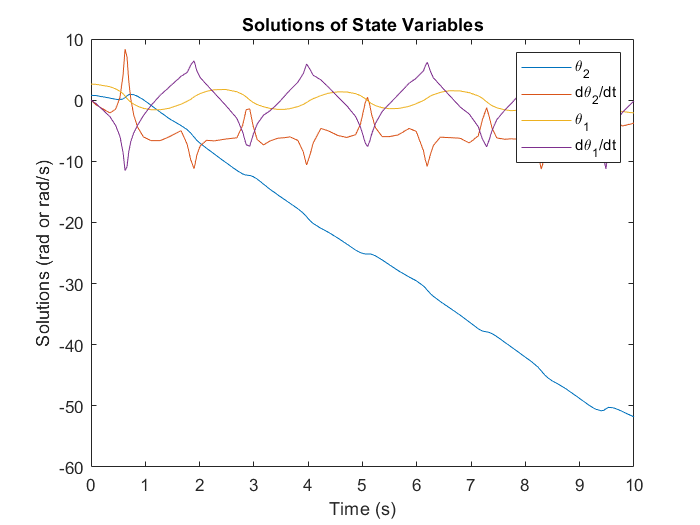

%Plot
plot(sols.x,sols.y)
legend('\theta_2','d\theta_2/dt','\theta_1','d\theta_1/dt')
title('Solutions of State Variables')
xlabel('Time (s)')
ylabel('Solutions (rad or rad/s)')

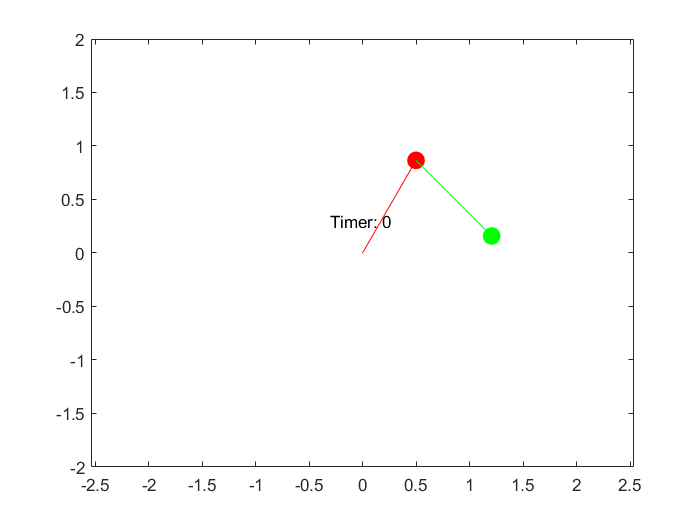

%Make animation
x_1 = @(t) L_1*sin(deval(sols,t,3));
y_1 = @(t) -L_1*cos(deval(sols,t,3));
x_2 = @(t) L_1*sin(deval(sols,t,3))+L_2*sin(deval(sols,t,1));
y_2 = @(t) -L_1*cos(deval(sols,t,3))-L_2*cos(deval(sols,t,1));

fanimator(@(t) plot(x_1(t),y_1(t),'ro','MarkerSize',m_1*10,'MarkerFaceColor','r'));
axis equal;

hold on;
fanimator(@(t) plot([0 x_1(t)],[0 y_1(t)],'r-'));
fanimator(@(t) plot(x_2(t),y_2(t),'go','MarkerSize',m_2*10,'MarkerFaceColor','g'));
fanimator(@(t) plot([x_1(t) x_2(t)],[y_1(t) y_2(t)],'g-'));

fanimator(@(t) text(-0.3,0.3,"Timer: "+num2str(t,2)));
hold off;

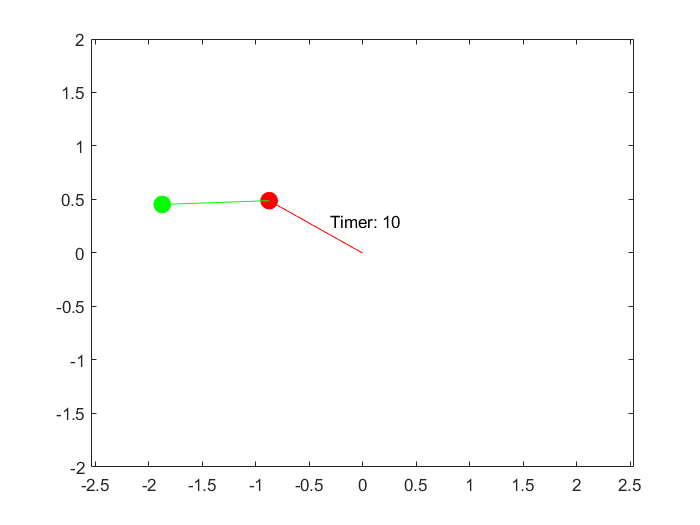

playAnimation